## Supplemental script to "Simulation of Steady State Energy Metabolism in Cyling and Running"

### Script for creating Figure 1

*Script written by Oliver Jan Quittmann in 2019 and commented by Simon Nolte in 2022.*

####  Setup

clc
clearvars
close all
% Define colours
purple = [0.5 0 0.5];
pink = [0.9 0 0.9];
blue = [0 0 1];
turq = [0 0.9 0.9];
green = [0 0.8 0];
yellow = [1 0.8 0];
orange = [1 0.5 0];
red = [1 0.2 0];
brown = [0.7 0 0];
black = [0 0 0];

red_base = [1 0.2 0];
red_0_5 = [0.20 0.2 0];

% Define line sizes
thick = 3;
thin = 1;

#### Set values

% Specify ADP range
ADP(:,1) = 0:0.001:1000;

% Specify range of constants
kox = [0.2, 0.25, 0.33, 0.5, 1, 2 3 4 5];
nox = kox;

VO2max = 1;

% Calculuate activation lines
    for a = 1:length(ADP)    
       
VO2_base(a,1) = (VO2max/(1+(kox(5)/(ADP(a)))^nox(5)));
VO2_kox_0_5(a,1) = (VO2max/(1+(kox(1)/(ADP(a)))^nox(5))); 
VO2_kox_0_4(a,1) = (VO2max/(1+(kox(2)/(ADP(a)))^nox(5))); 
VO2_kox_0_3(a,1) = (VO2max/(1+(kox(3)/(ADP(a)))^nox(5))); 
VO2_kox_0_2(a,1) = (VO2max/(1+(kox(4)/(ADP(a)))^nox(5))); 
VO2_kox_2(a,1) = (VO2max/(1+(kox(6)/(ADP(a)))^nox(5))); 
VO2_kox_3(a,1) = (VO2max/(1+(kox(7)/(ADP(a)))^nox(5))); 
VO2_kox_4(a,1) = (VO2max/(1+(kox(8)/(ADP(a)))^nox(5))); 
VO2_kox_5(a,1) = (VO2max/(1+(kox(9)/(ADP(a)))^nox(5)));

VO2_nox_0_5(a,1) = (VO2max/(1+(kox(5)/(ADP(a)))^nox(1))); 
VO2_nox_0_4(a,1) = (VO2max/(1+(kox(5)/(ADP(a)))^nox(2))); 
VO2_nox_0_3(a,1) = (VO2max/(1+(kox(5)/(ADP(a)))^nox(3))); 
VO2_nox_0_2(a,1) = (VO2max/(1+(kox(5)/(ADP(a)))^nox(4))); 
VO2_nox_2(a,1) = (VO2max/(1+(kox(5)/(ADP(a)))^nox(6))); 
VO2_nox_3(a,1) = (VO2max/(1+(kox(5)/(ADP(a)))^nox(7))); 
VO2_nox_4(a,1) = (VO2max/(1+(kox(5)/(ADP(a)))^nox(8))); 
VO2_nox_5(a,1) = (VO2max/(1+(kox(5)/(ADP(a)))^nox(9)));
    end
    
base = VO2_base/ VO2max;
kox_0_5 = VO2_kox_0_5/VO2max;
kox_0_4 = VO2_kox_0_4/VO2max;
kox_0_3 = VO2_kox_0_3/VO2max;
kox_0_2 = VO2_kox_0_2/VO2max;
kox_2 = VO2_kox_2/VO2max;
kox_3 = VO2_kox_3/VO2max;
kox_4 = VO2_kox_4/VO2max;
kox_5 = VO2_kox_5/VO2max;

nox_0_5 = VO2_nox_0_5/VO2max;
nox_0_4 = VO2_nox_0_4/VO2max;
nox_0_3 = VO2_nox_0_3/VO2max;
nox_0_2 = VO2_nox_0_2/VO2max;
nox_2 = VO2_nox_2/VO2max;
nox_3 = VO2_nox_3/VO2max;
nox_4 = VO2_nox_4/VO2max;
nox_5 = VO2_nox_5/VO2max;

#### Create plot: K_ox subplot

subplot(2,1,1)

% Plot lines
semilogx(ADP,kox_0_5,'-','LineWidth',thin, 'Color', brown)
hold on
semilogx(ADP,kox_0_4,'-','LineWidth',thin, 'Color', red)
semilogx(ADP,kox_0_3,'-','LineWidth',thin, 'Color', orange)
semilogx(ADP,kox_0_2,'-','LineWidth',thin, 'Color', yellow)
semilogx(ADP,base,'-','LineWidth',thick, 'Color', black)
semilogx(ADP,kox_2,'-','LineWidth',thin, 'Color', green)
semilogx(ADP,kox_3,'-','LineWidth',thin, 'Color', turq)
semilogx(ADP,kox_4,'-','LineWidth',thin, 'Color', blue)
semilogx(ADP,kox_5,'-','LineWidth',thin, 'Color', pink)
plot([0.0001,1],[0.5,0.5],'--','LineWidth',thin, 'Color', black)
plot([1,1],[0,0.5],'--','LineWidth',thin, 'Color', black)

% Set lables
x = xlabel('$[ADP]$', 'interpreter','latex','fontweight','bold')

x =   Text ($[ADP]$) with properties:

                 String: '$[ADP]$'
               FontSize: 9.9000
             FontWeight: 'bold'
               FontName: 'Helvetica'
                  Color: [0.1500 0.1500 0.1500]
    HorizontalAlignment: 'center'
               Position: [1000 -0.0700 -1]
                  Units: 'data'

  Show all properties


y = ylabel('$\%\dot{V}O_2$', 'interpreter','latex');
set(y, 'Position', [0.0003 0.98 -1], 'Rotation', 0)
set(x, 'Position', [1000 -0.07 -1], 'Rotation', 0)

% Set legend, subplot title and axes
l_legend = legend ('0.20','0.25','0.33','0.50','1','2','3','4','5', 'interpreter','latex','Location','southeast')

l_legend =   Legend (0.20, 0.25, 0.33, 0.50, 1, 2, 3, 4, 5) with properties:

         String: {'0.20'  '0.25'  '0.33'  '0.50'  '1'  '2'  '3'  '4'  '5'}
       Location: 'southeast'
    Orientation: 'vertical'
       FontSize: 8.1000
       Position: [0.7604 0.6039 0.1254 0.2968]
          Units: 'normalized'

  Show all properties


%l_legend = legend ('0.20','0.25','0.33','0.50','1','2','3','4','5', 'Location','southeast');
t = title('$$K_{ox}$$','interpreter','latex', 'FontSize',20, 'FontWeight', 'bold')

t =   Text ($$K_{ox}$$) with properties:

                 String: '$$K_{ox}$$'
               FontSize: 20
             FontWeight: 'bold'
               FontName: 'Helvetica'
                  Color: [0 0 0]
    HorizontalAlignment: 'center'
               Position: [1.0000 1.0233 1.4433e-14]
                  Units: 'data'

  Show all properties


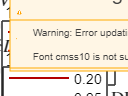

axis ([0.001, 1000, 0, 1])

#### Create plot: n_ox subplot

subplot(2,1,2)

% Plot lines
semilogx(ADP,nox_0_5,'-','LineWidth',thin, 'Color', brown);
hold on
semilogx(ADP,nox_0_4,'-','LineWidth',thin, 'Color', red);
semilogx(ADP,nox_0_3,'-','LineWidth',thin, 'Color', orange);
semilogx(ADP,nox_0_2,'-','LineWidth',thin, 'Color', yellow);
semilogx(ADP,base,'-','LineWidth',thick, 'Color', black);
semilogx(ADP,nox_2,'-','LineWidth',thin, 'Color', green);
semilogx(ADP,nox_3,'-','LineWidth',thin, 'Color', turq);
semilogx(ADP,nox_4,'-','LineWidth',thin, 'Color', blue);
semilogx(ADP,nox_5,'-','LineWidth',thin, 'Color', pink);

% Set labels
x = xlabel('$[ADP]$', 'interpreter','latex','fontweight','bold');
y = ylabel('$\%\dot{c}La_{pr}$', 'interpreter','latex');
set(y, 'Position', [0.0003 0.98 -1], 'Rotation', 0)
set(x, 'Position', [1000 -0.07 -1], 'Rotation', 0)

% Set legend, subplot title and axes
l_legend = legend ('0.20','0.25','0.33','0.50','1','2','3','4','5', 'interpreter','latex','Location','southeast')

l_legend =   Legend (0.20, 0.25, 0.33, 0.50, 1, 2, 3, 4, 5) with properties:

         String: {'0.20'  '0.25'  '0.33'  '0.50'  '1'  '2'  '3'  '4'  '5'}
       Location: 'southeast'
    Orientation: 'vertical'
       FontSize: 8.1000
       Position: [0.7604 0.1293 0.1254 0.2968]
          Units: 'normalized'

  Show all properties


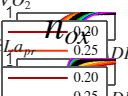

%l_legend = legend ('0.20','0.25','0.33','0.50','1','2','3','4','5','Location','southeast');
%x = title('n_{OX}', 'interpreter','tex', 'FontSize',18);
title('$$n_{ox}$$','interpreter','latex', 'FontSize',20, 'FontWeight', 'bold');
axis ([0.001, 1000, 0, 1])

#### Write plot file

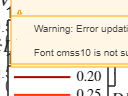

set(gcf,'PaperUnits','inches','PaperPosition',[0 0 6 10])
FigureTitle_print = strcat({'../plots/Fig1'});
path_name = fullfile('.', '..', '/plots/Fig1.png');
print(path_name,'-dpng', '-r1000');